# S-Bahn-Ring: Simulation für Aufgabe 2.2

Dieses Live-Skript ist die zentrale Bedienoberfläche: Einstellungen auswählen, Simulation starten und die Ergebnisse hier auswerten. Der gemeinsame Modellkern liegt im Paket sbahn. Einstellungen, Strecke und Zugzustände sind getrennt: p.config, p.route und p.state. In den Zugarrays entspricht der Index der Zugnummer.

## Modell und Annahmen

Eine Fahrtrichtung, standardmäßig zwölf Züge und 27 Stationen. Das Fahrmodell ist wählbar: konstantes On/Off-Fahren oder Beschleunigen und Bremsen mit mehreren Geschwindigkeitsstufen. Das Haltezeitmodell ist wählbar: einheitliche Halte oder stationsabhängige geplante S41-Haltezeiten aus dem VBB-GTFS-Fahrplan. Jeder Zug ist 148 m lang (vereinfachter Vollzug aus zwei BR 484). Die Stationen bleiben ideale Haltepunkte der Zugspitze. Zugkörper und optionale Blockabschnitte verhindern Kollisionen und Überholen; gezielte Zusatzhalte, zufällige Zusatzhalte und zeitweise Blocksperren sind einzeln zuschaltbar.

Im On/Off-Modell dauert der Standardumlauf bei einheitlichen 30 Sekunden Halt 60 Minuten: 2790 Sekunden Fahrt plus 810 Sekunden Stationshalte. Der Zeitschritt beträgt eine Sekunde. Im On/Off-Modell ergibt sich die Zelllänge aus der Streckenlänge geteilt durch 2790. Das neue Fahrmodell verwendet dagegen genau Δx = 1 m, Δt = 1 s und eine auf ganze Meter gerundete Ringlänge. Änderungen der Haltezeit verändern die Umlaufzeit; eine Änderung der Zugzahl verändert die erwartete Zugfolge.

## Einstellungen

Änderungen gelten erst beim nächsten Start. Wähle zuerst die Streckengrundlage und dann die Darstellung. Der geografische Streckenverlauf ist nur mit der realen Ringbahn S41 verfügbar. Die Auswahl verändert keine Dateien.

streckengrundlage = "Reale Ringbahn S41";
darstellung = "Geografischer Streckenverlauf";
fahrmodell = "Beschleunigen und Bremsen";
zugzahl = 12;
blocksteuerung = "OSM-Signalabschnitte";
blockabstandMeter = 500;
haltezeitmodell = "GTFS-Stationshalte";
haltezeitSekunden = 30;
simulationsdauerMinuten = 120;
animation = true;
bildpauseSekunden = 0.05;
bildabstandSchritte = 10;

Im Fahrmodell „Beschleunigen und Bremsen“ steigt oder sinkt die Geschwindigkeit pro Sekunde höchstens um 1 m/s. Die Geschwindigkeitsstufen betragen 3,6 km/h, maximal sind 79,2 km/h zulässig (unterhalb der Grenze von 80 km/h). Der diskrete Bremsweg lautet B(v) = v(v+1)/2 Meter. Gewählt wird die höchste noch abbremsbare Geschwindigkeit vor der nächsten Station, dem vorausfahrenden Zugende oder einer gesperrten Blockgrenze. Ein Stationshalt muss in diesem Modus mindestens eine Sekunde dauern, damit der Zug vollständig zum Stillstand kommt. Die freie Umlaufzeit wird aus einem Referenzumlauf berechnet und nicht auf 60 Minuten kalibriert.

„GTFS-Stationshalte“ benötigt die reale Ringbahn S41. Verwendet wird je Station der Median gültiger Zwischenhalte aller aktiven S41-Fahrten am 14.10.2026. Tripanfang und Tripende werden ausgeschlossen, da dort Haltezeiten fehlen können. Das Zahlenfeld für den einheitlichen Stationshalt wirkt nur im Modus „Einheitlich“. Die Daten sind geplante Zeiten, keine Ist-Messungen. Alle Züge verwenden zunächst dasselbe Stationsprofil.

Blocksteuerung: „Ohne Blocksteuerung“ prüft nur den Abstand zum Zugende. „Gleichmäßige Blockabschnitte“ verteilt ceil(Streckenlänge / Zielabstand) Abschnitte über den gesamten Ring; die tatsächlich gerundeten Längen stehen nach dem Start in der Konfiguration. „OSM-Signalabschnitte“ verwendet 117 gerichtete Haupt-/Mehrabschnittssignale des lokalen S41-Datenstands. Diese Signalabstände sind eine Annäherung, keine bestätigten betrieblichen Blöcke. Die OSM-Auswahl benötigt die reale Strecke; der Zielabstand wirkt ausschließlich bei gleichmäßigen Abschnitten.

Ein Zug belegt alle Abschnitte, die sein Körper berührt. Ein fremdbelegter Abschnitt darf erst im Zeitschritt nach vollständiger Räumung durch das Zugende befahren werden. Auch kürzere Blöcke als die Zuglänge sind zulässig. Grün/rote Punkte in der Animation zeigen freie/belegte Blockanfänge; dicke Linien zeigen Zugkörper und kleine Punkte die Spitzen. Die Zuglänge gilt in allen drei Modi; im groben On/Off-Raster wird auf ganze belegte Zellen aufgerundet, im dynamischen Modell sind es genau 148 Meterzellen.

Die Startpositionen stammen weiterhin aus gleichmäßig versetzten freien Umlaufphasen. Überlappende Zugkörper oder gemeinsam belegte Startblöcke werden abgewiesen: dann Zugzahl oder Zielabstand verringern. Vor gesperrten Blöcken wird eine zu hohe Startgeschwindigkeit abgesenkt; dadurch kann anfangs ein Einschwingvorgang entstehen. Die angezeigte Referenzzugfolge beschreibt den freien Verkehr, keine garantierte Kapazität der Blöcke.

Bildpause und Bildabstand steuern nur das Wiedergabetempo. Die reale Simulation verwendet weiterhin Δt = 1 s. Zum schnellen Rechnen kann die Animation ausgeschaltet werden.

## Störungen auswählen

Alle Störungen sind zunächst ausgeschaltet. Die Werte sind frei gewählte Experimente, keine aus Betriebsdaten geschätzten Ausfallraten. Änderungen gelten erst beim nächsten Start. Alle Zeitangaben hier sind Sekunden ab Simulationsbeginn beziehungsweise zusätzliche Sekunden Halt.

**Gezielter Zusatzhalt:** Genau eine Aufenthaltsverlängerung bei der ersten Ankunft des gewählten Zuges an der gewählten Station ab dem angegebenen Zeitpunkt. Bereits beim Start laufende Stationshalte werden nicht nachträglich verlängert. Stationsnummern stehen unten in der Stationstabelle; auf dem idealisierten Ring entsprechen sie H01 bis H27.

gezielterZusatzhalt = true;
stoerungszug = 1;
stoerungsstation = 1;
zusatzhaltAbSekunden = 900;
gezielterZusatzSekunden = 300;

**Zufällige Zusatzhalte:** Bei jeder Ankunft wird einmal mit der gewählten Wahrscheinlichkeit entschieden. Bei einem Treffer wird eine ganzzahlige Dauer gleichverteilt zwischen Minimum und Maximum gezogen. Beispielwerte: 5 Prozent pro Ankunft, zusätzlich 30 bis 120 Sekunden. Derselbe Zufallsstartwert reproduziert den Lauf; Animation und Wiedergabetempo verändern ihn nicht. Treffen beide Zusatzhalte zusammen, werden ihre Dauern addiert. Zuerst wird der geplante Halt abgewartet, anschließend der Zusatzhalt.

zufaelligeZusatzhalte = true;
zusatzhaltWahrscheinlichkeitProzent = 5;
zufallsminimumSekunden = 30;
zufallsmaximumSekunden = 120;
zufallsstartwert = 42;

**Zeitweise Blocksperre:** Ein Blockzugang bleibt während des gewählten Zeitfensters gesperrt. Blocknummern folgen den Abschnittsanfängen in Fahrtrichtung; Anzahl und Position des gewählten Zugangs stehen nach dem Start in der aktiven Konfiguration. Die Sperre benötigt gleichmäßige oder OSM-Blockabschnitte. Bereits eingefahrene Züge dürfen weiterfahren. Ein Zug, der beim Sperrbeginn nicht mehr mit höchstens 1 m/s² davor stoppen könnte, erhält noch genau eine Einfahrt; er wird im Protokoll ausgewiesen. Nach Ende der Sperre gelten wieder die normalen Belegungsregeln. Das ist eine vereinfachte Zugangssperre, kein vollständiges betriebliches Signalausfallverfahren.

blocksperre = true;
gesperrterBlock = 1;
sperrbeginnSekunden = 900;
sperrdauerSekunden = 300;

## Simulation starten

Mit „Simulation starten“ werden die gewählten Einstellungen übernommen und alle Ergebnisse neu berechnet. Alternativ führt „Run“ das vollständige Live-Skript aus. Die Animation läuft während der Berechnung. Anschließend dokumentieren die Angaben die tatsächlich verwendete Konfiguration. Die Vorbereitung erfolgt genau einmal pro Start.

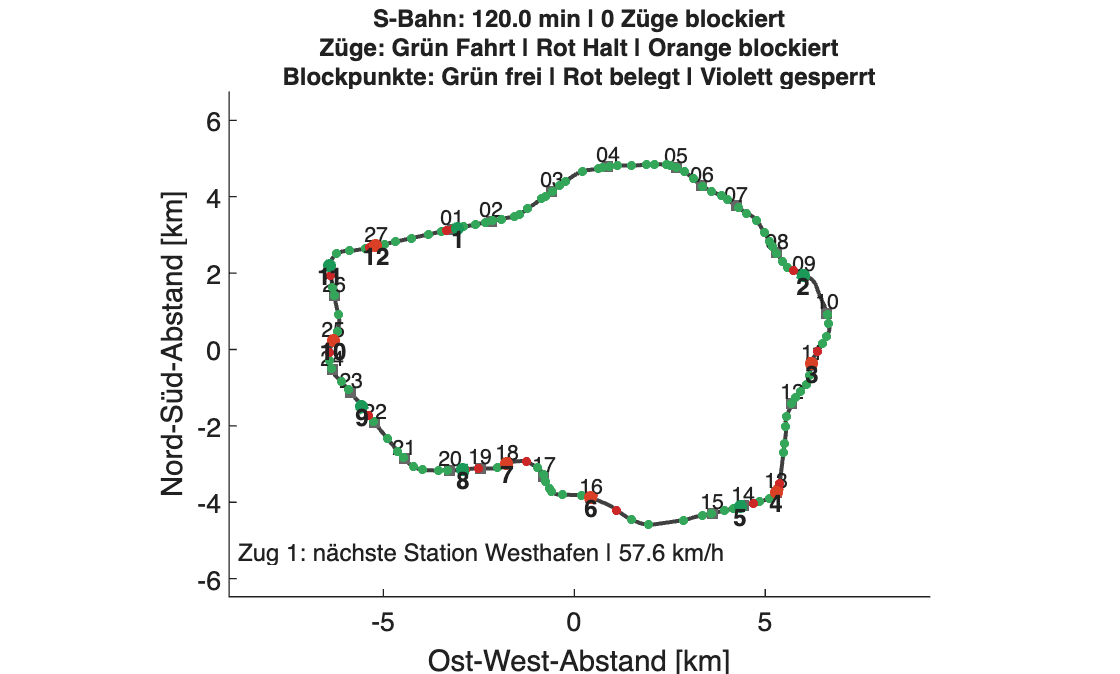

                Einstellung                             Wert              
    ___________________________________    _______________________________

    "Streckengrundlage"                    "Reale Ringbahn S41"           
    "Darstellung"                          "Geografischer Streckenverlauf"
    "Fahrmodell"                           "Beschleunigen und Bremsen"    
    "Züge"                                 "12"                           
    "Blocksteuerung"                       "OSM-Signalabschnitte"         
    "Blockanzahl"                          "117"                          
    "Blocklängen min–max"                  "104–1207 m"                   
    "Zuglänge im Raster"                   "148.00 m (148 Zellen)"        
    "Haltezeitmodell"                      "GTFS-Stationshalte"           
    "Stationshalte min–max"                "30–48 s"                      
    "Simulationsdauer"         

Blockgrundlage: 117 gerichtete OSM-Signalkandidaten (14.10.2026); betrieblich unbestätigt


          Störungseinstellung                   Wert          
    _______________________________    _______________________

    "Gezielter Zusatzhalt"             "true"                 
    "Zug / Station / ab / Zusatz"      "1 / 1 / 900 s / 300 s"
    "Zufällige Zusatzhalte"            "true"                 
    "Wahrscheinlichkeit je Ankunft"    "5 %"                  
    "Zufallsdauer min–max"             "30–120 s"             
    "Zufallsstartwert"                 "42"                   
    "Blocksperre"                      "true"                 
    "Blocknummer / Anfang"             "1 / 0.031 km"         
    "Sperrbeginn / Dauer"              "900 s / 300 s"        



 
laufErfolgreich = false;
projektordner = fileparts(matlab.desktop.editor.getActiveFilename);
if isfolder(fullfile(projektordner,'+sbahn'))
    addpath(projektordner);
end
assert(~isempty(which('sbahn.simulate')),'SBahn:ProjectFolder', ...
    'Bitte SBahn_demo.mlx aus dem vollständigen S-Bahn-Projektordner öffnen.');
config = struct('trackMode',streckengrundlage,'displayMode',darstellung, ...
    'blockMode',blocksteuerung,'blockLengthMeters',blockabstandMeter, ...
    'motionModel',fahrmodell,'trainCount',zugzahl,'dwellMode',haltezeitmodell,'stopSeconds',haltezeitSekunden, ...
    'durationMinutes',simulationsdauerMinuten,'animate',animation, ...
    'framePauseSeconds',bildpauseSekunden,'displayEvery',bildabstandSchritte, ...
    'targetStopEnabled',gezielterZusatzhalt,'targetStopTrain',stoerungszug,'targetStopStation',stoerungsstation, ...
    'targetStopAfterSeconds',zusatzhaltAbSekunden,'targetStopSeconds',gezielterZusatzSekunden, ...
    'randomStopEnabled',zufaelligeZusatzhalte,'randomStopProbability',zusatzhaltWahrscheinlichkeitProzent/100, ...
    'randomStopMinSeconds',zufallsminimumSekunden,'randomStopMaxSeconds',zufallsmaximumSekunden,'randomSeed',zufallsstartwert, ...
    'closureEnabled',blocksperre,'closureBlock',gesperrterBlock, ...
    'closureStartSeconds',sperrbeginnSekunden,'closureDurationSeconds',sperrdauerSekunden);
try
    [G,p,report] = sbahn.simulate(config);
    verwendet = p.config;
    blocklaengen = "Keine";
    if ~isempty(p.blocks.lengthMeters)
        blocklaengen = compose('%g–%g m',min(p.blocks.lengthMeters),max(p.blocks.lengthMeters));
    end
    aktiveEinstellungen = table( ...
        ["Streckengrundlage";"Darstellung";"Fahrmodell";"Züge";"Blocksteuerung";"Blockanzahl";"Blocklängen min–max";"Zuglänge im Raster";"Haltezeitmodell";"Stationshalte min–max"; ...
        "Simulationsdauer";"Animation";"Bildpause";"Bildabstand"; ...
        "Streckenlänge";"Δt";"Δx";"Höchste Geschwindigkeitsstufe";"Beschleunigung / Bremsverzögerung"; ...
        "Freier Referenzumlauf";"Freie Referenzzugfolge"], ...
        [verwendet.trackMode;verwendet.displayMode;verwendet.motionModel;string(verwendet.trainCount);verwendet.blockMode;string(report.blockCount);blocklaengen; ...
        compose('%.2f m (%g Zellen)',p.effectiveTrainLengthMeters,p.trainCells);verwendet.dwellMode; ...
        compose('%g–%g s',min(p.stationDwellSeconds),max(p.stationDwellSeconds));string(verwendet.durationMinutes)+" min"; ...
        string(verwendet.animate);string(verwendet.framePauseSeconds)+" s"; ...
        string(verwendet.displayEvery)+" Schritte"; ...
        compose('%.4f km',p.route.lengthMeters/1000); ...
        "1 s";compose('%.5f m',p.dxMeters); ...
        compose('%.2f km/h',p.driveSpeedKmh); ...
        compose('%g / %g m/s²',p.accelerationMetersPerSecondSquared,p.brakingMetersPerSecondSquared);  ...
        string(p.expectedLapSeconds/60)+" min"; ...
        string(p.expectedHeadwaySeconds/60)+" min"], ...
        'VariableNames',{'Einstellung','Wert'});
    disp(aktiveEinstellungen)
    disp("Blockgrundlage: " + p.blocks.source)
    stoerungseinstellungen = table( ...
        ["Gezielter Zusatzhalt";"Zug / Station / ab / Zusatz";"Zufällige Zusatzhalte"; ...
        "Wahrscheinlichkeit je Ankunft";"Zufallsdauer min–max";"Zufallsstartwert"; ...
        "Blocksperre";"Blocknummer / Anfang";"Sperrbeginn / Dauer"], ...
        [string(verwendet.targetStopEnabled);compose('%g / %g / %g s / %g s', ...
        verwendet.targetStopTrain,verwendet.targetStopStation,verwendet.targetStopAfterSeconds,verwendet.targetStopSeconds); ...
        string(verwendet.randomStopEnabled);string(100*verwendet.randomStopProbability)+" %"; ...
        compose('%g–%g s',verwendet.randomStopMinSeconds,verwendet.randomStopMaxSeconds);string(verwendet.randomSeed); ...
        string(verwendet.closureEnabled);"Aus"; ...
        compose('%g s / %g s',verwendet.closureStartSeconds,verwendet.closureDurationSeconds)], ...
        'VariableNames',{'Störungseinstellung','Wert'});
    if verwendet.closureEnabled
        stoerungseinstellungen.Wert(8) = compose('%g / %.3f km',verwendet.closureBlock, ...
            (p.blocks.startCells(verwendet.closureBlock)-1)*p.dxMeters/1000);
    end
    disp(stoerungseinstellungen)
    laufErfolgreich = true;
    if ~animation, disp("Animation ausgeschaltet. Simulation abgeschlossen."); end
catch fehler
    G = []; p = []; report = [];
    disp("Simulation nicht abgeschlossen: " + string(fehler.message))
end

## Auswertung: Zeit-Weg-Diagramm

Die horizontale Achse zeigt die Position auf dem Ring in Kilometern, die vertikale Achse die Simulationszeit in Minuten. Dunkle Punkte kennzeichnen Stillstand; orange Punkte markieren Blockierungen durch Zugenden oder gesperrte Blockabschnitte. Violett kennzeichnet abgewartete Zusatzhalte und Stillstand vor einer zeitweisen Blocksperre. Linien werden am Ringübergang unterbrochen.

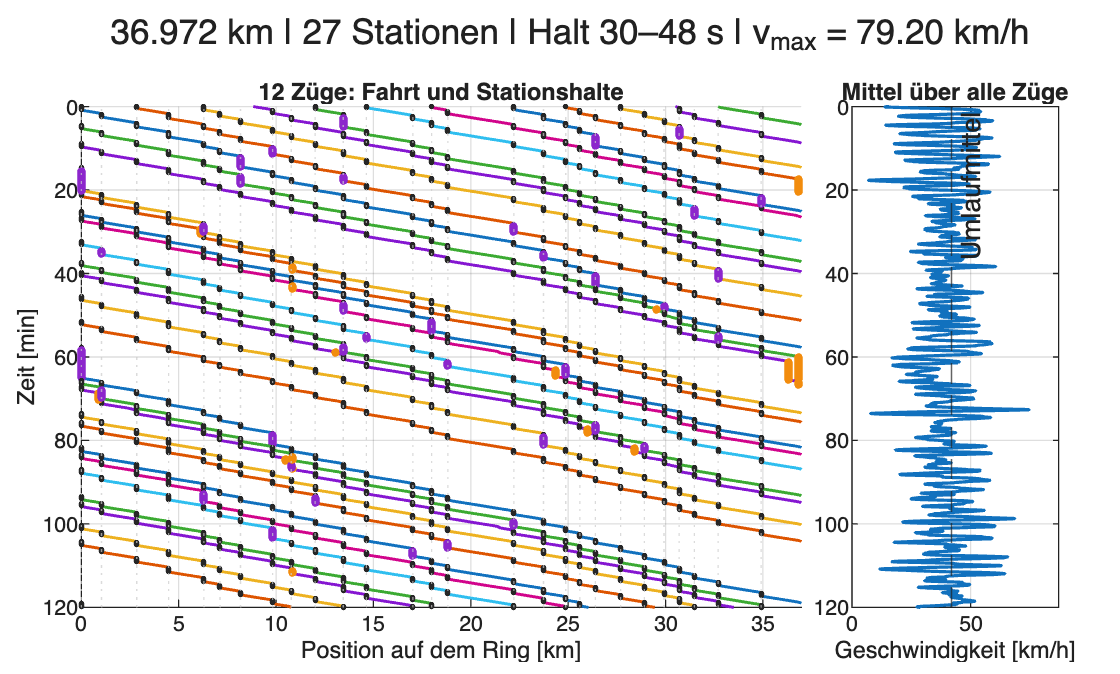

if laufErfolgreich
    sbahn.plotResults(G,p);
else
    disp("Keine Auswertung für die zuletzt gewählten Einstellungen verfügbar.")
end

## Fahrbewegung: Zug 1

Oben steht die Geschwindigkeit von Zug 1, darunter ihre Änderung pro Sekunde. Im neuen Fahrmodell sind Anfahren und Bremsen auf höchstens ±1 m/s² begrenzt. Im On/Off-Vergleich sind die sofortigen Geschwindigkeitswechsel weiterhin Teil der ursprünglichen Annahme. Die Geschwindigkeit bezeichnet den im letzten Zeitschritt zurückgelegten Weg geteilt durch Δt.

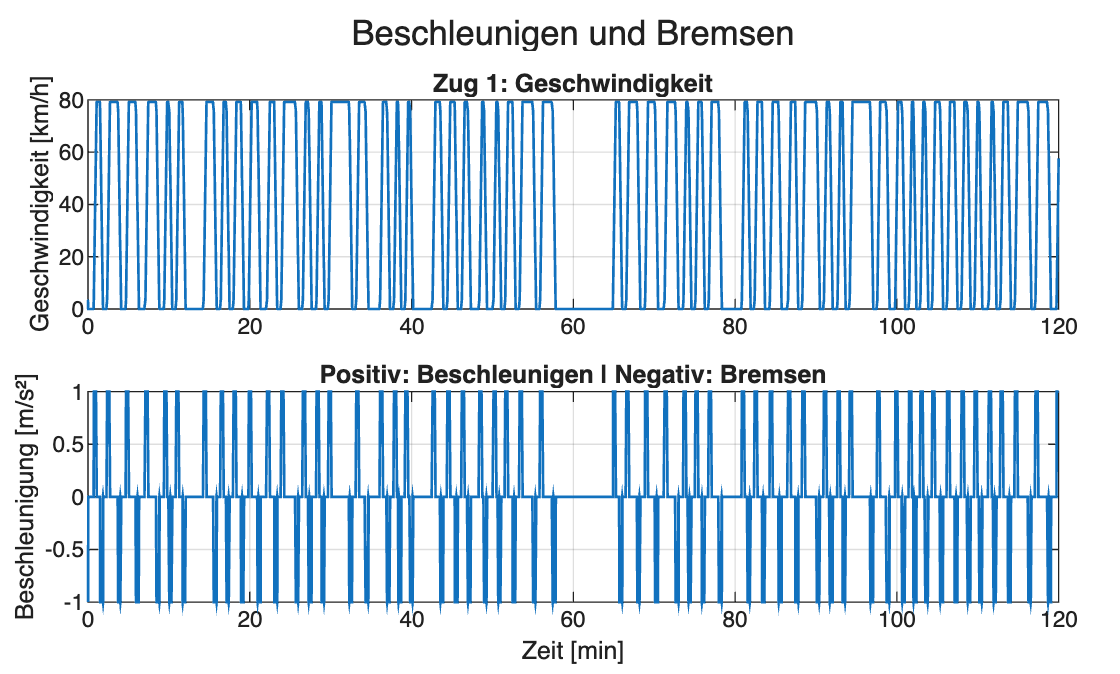

if laufErfolgreich
    sbahn.plotDynamics(G,p);
else
    disp("Keine aktuelle Fahrbewegung verfügbar.")
end

## Kennzahlen und Stationen

Gemessene Umlauf- und Haltezeiten benötigen vollständig beobachtete Ereignisse. Bei kurzen Simulationen kann deshalb NaN erscheinen. Die erwarteten Werte stehen oben unabhängig davon zur Verfügung. Bei der geografischen Animation entsprechen die Stationsnummern dieser Tabelle.

if laufErfolgreich
    kennzahlen = table( ...
        ["Züge";"Gemessener Umlauf [min]";"Gemessene Zugfolge [min]"; ...
        "Gemessener Stationshalt [s]";"Höchste Geschwindigkeitsstufe [km/h]";"Gemessene Höchstgeschwindigkeit [km/h]";"Mittlere Geschwindigkeit [km/h]"; ...
        "Blockierte Zugsekunden";"Davon vor belegtem Block";"Maximal gleichzeitig blockiert"], ...
        [report.trainCount;report.meanLapSeconds/60; ...
        report.meanHeadwaySeconds/60;report.meanDwellSeconds; ...
        report.driveSpeedKmh;report.maxObservedSpeedKmh;report.meanSpeedKmh; ...
        report.blockedTrainSeconds;report.signalBlockedTrainSeconds;report.maxSimultaneouslyBlocked], ...
        'VariableNames',{'Kennzahl','Wert'});
    disp(kennzahlen)
    stationen = table((1:p.stationCount)',p.route.stationNames', ...
        (p.route.stationCells'-1)*p.dxMeters/1000, ...
        p.stationDwellSeconds',p.dwellSampleCounts', ...
        'VariableNames',{'Nr','Station','Position_km','Halt_s','Quellhalte'});
    disp(stationen)
    disp("Haltezeitquelle: " + p.dwellSource)
    if report.blockedTrainSeconds == 0
        disp("Keine Blockierungen in diesem Lauf. Identische Stationsprofile und gleichmäßig versetzte Züge können trotz unterschiedlicher Stationshalte staufrei bleiben.")
    end
else
    disp("Keine aktuellen Kennzahlen verfügbar.")
end

                    Kennzahl                     Wert 
    ________________________________________    ______

    "Züge"                                          12
    "Gemessener Umlauf [min]"                   56.776
    "Gemessene Zugfolge [min]"                  4.9597
    "Gemessener Stationshalt [s]"               38.151
    "Höchste Geschwindigkeitsstufe [km/h]"        79.2
    "Gemessene Höchstgeschwindigkeit [km/h]"      79.2
    "Mittlere Geschwindigkeit [km/h]"           39.529
    "Blockierte Zugsekunden"                      1479
    "Davon vor belegtem Block"                    1479
    "Maximal gleichzeitig blockiert"                 3



    Nr           Station           Position_km    Halt_s    Quellhalte
    __    _____________________    ___________    ______    __________

     1    "Beusselstraße"                 0         42          16    
     2    "Westhafen"                 1.035         30         219    
     3    "Wedding"                   2.846         36         219    
     4    "Gesundbrunnen"             4.485         48         218    
     5    "Schönhauser Allee"          6.29         36         220    
     6    "Prenzlauer Allee"          7.119         30         220    
     7    "Greifswalder Straße"       8.174         30         217    
     8    "Landsberger Allee"         9.826         30         197    
     9    "Storkower Straße"         10.779         30         207    
    10    "Frankfurter Allee"        12.003     

Haltezeitquelle: VBB-GTFS: Median gültiger S41-Zwischenhalte am 14.10.2026; geplante Zeiten, keine Ist-Messungen


## Störungsauswertung

Zugewiesene Zusatzzeit umfasst alle ausgelösten Ereignisse, auch noch laufende Halte am Simulationsende. Beobachtete Zusatzzeit zählt nur tatsächlich simulierte Sekunden nach Ablauf des geplanten Halts. Sperrwartezeit ist Teil der gesamten Blockwartezeit; Wartezeit wegen gewöhnlicher Blockbelegung wird getrennt ausgewiesen. Die Ursache einer gesamten Verspätung lässt sich daraus noch nicht eindeutig zuordnen.

if laufErfolgreich
    stoerungskennzahlen = table( ...
        ["Gezielte Zusatzhalte";"Zufällige Zusatzhalte";"Zugewiesener gezielter Zusatz [s]"; ...
        "Zugewiesener Zufallszusatz [s]";"Beobachteter Zusatzhalt [Zug·s]"; ...
        "Geplanter Stationshalt [Zug·s]";"Warten vor gesperrtem Zugang [Zug·s]"; ...
        "Warten vor gewöhnlich belegtem Block [Zug·s]";"Letzte Einfahrerlaubnisse"], ...
        [report.targetedStopCount;report.randomStopCount;report.assignedTargetedSeconds; ...
        report.assignedRandomSeconds;report.observedExtraHoldTrainSeconds;report.plannedHoldTrainSeconds; ...
        report.closureBlockedTrainSeconds;report.occupiedBlockTrainSeconds;report.closureGraceCount], ...
        'VariableNames',{'Kennzahl','Wert'});
    disp(stoerungskennzahlen)
    ereignisse = p.state.stopLog(any(p.state.stopLog(:,5:6) > 0,2),:);
    if ~isempty(ereignisse)
        auswahl = ereignisse(1:min(20,size(ereignisse,1)),:);
        zusatzhalte = table(auswahl(:,1)/60,auswahl(:,2), ...
            reshape(p.route.stationNames(auswahl(:,3)),[],1),auswahl(:,4),auswahl(:,5),auswahl(:,6), ...
            'VariableNames',{'Zeit_min','Zug','Station','Geplant_s','Gezielter_Zusatz_s','Zufallszusatz_s'});
        disp("Erste höchstens 20 Zusatzhalte; alle Ereignisse stehen in p.state.stopLog.")
        disp(zusatzhalte)
    end
    if ~isempty(p.state.closureGraceLog)
        letzteEinfahrten = array2table(p.state.closureGraceLog, ...
            'VariableNames',{'Sperrbeginn_s','Zug','Block'});
        disp(letzteEinfahrten)
    end
else
    disp("Keine aktuelle Störungsauswertung verfügbar.")
end

                       Kennzahl                       Wert 
    ______________________________________________    _____

    "Gezielte Zusatzhalte"                                1
    "Zufällige Zusatzhalte"                              36
    "Zugewiesener gezielter Zusatz [s]"                 300
    "Zugewiesener Zufallszusatz [s]"                   2710
    "Beobachteter Zusatzhalt [Zug·s]"                  3010
    "Geplanter Stationshalt [Zug·s]"                  23466
    "Warten vor gesperrtem Zugang [Zug·s]"              269
    "Warten vor gewöhnlich belegtem Block [Zug·s]"     1210
    "Letzte Einfahrerlaubnisse"                           0



Erste höchstens 20 Zusatzhalte; alle Ereignisse stehen in p.state.stopLog.


    Zeit_min    Zug           Station           Geplant_s    Gezielter_Zusatz_s    Zufallszusatz_s
    ________    ___    _____________________    _________    __________________    _______________

     1.9667      5     "Ostkreuz"                  48                0                   118      
       4.75     10     "Westkreuz"                 48                0                    85      
     6.8833      8     "Bundesplatz"               30                0                   112      
     9.7667      2     "Landsberger Allee"         30                0                    59      
      12.05      1     "Greifswalder Straße"       30                0                   104      
     16.167      2     "Ostkreuz"                  48                0                    39      
   

## Modellprüfung und Grenzen

if laufErfolgreich
    assert(report.checksPassed);
    disp("Bestanden: konstante Zugzahl, überlappungsfreie Zugkörper und exklusive Blockbelegung.")
    disp("Ringübergang, Geschwindigkeiten, Stationsreihenfolge und Mindesthaltezeiten geprüft.")
    if p.config.motionModel == "Beschleunigen und Bremsen"
        disp("Bestanden: Beschleunigung und Bremsverzögerung höchstens 1 m/s²; kein Überspringen von Stationen oder Überholen.")
        disp("Rundung der Ringlänge: " + string(p.route.lengthMeters-p.route.sourceLengthMeters) + " m.")
    end
    disp("Größte Stationsrundung: " + string(report.maxStationRoundingMeters) + " m.")
    disp("Streckengrundlage: " + p.route.source)
else
    disp("Für diesen Start liegt keine bestandene Modellprüfung vor.")
end

Bestanden: konstante Zugzahl, überlappungsfreie Zugkörper und exklusive Blockbelegung.


Ringübergang, Geschwindigkeiten, Stationsreihenfolge und Mindesthaltezeiten geprüft.


Bestanden: Beschleunigung und Bremsverzögerung höchstens 1 m/s²; kein Überspringen von Stationen oder Überholen.


Rundung der Ringlänge: 0.401 m.


Größte Stationsrundung: 0.48 m.


Streckengrundlage: OpenStreetMap, S41; lokaler Datenstand 14.10.2026


Reale Stationsabstände bedeuten noch keine realistischen Fahrzeiten zwischen den Stationen: Beschleunigung und Bremsverzögerung sind vereinfachte konstante Modellparameter; die höchste Stufe gilt auf der ganzen Strecke. Abschnittsabhängige Geschwindigkeitsgrenzen fehlen noch. OSM-Signalabschnitte sind unbestätigte Modellgrenzen; Fahrstraßen, Durchrutschwege, ZBS und reale Freimeldegrenzen werden nicht nachgebildet. Beim vorausfahrenden Zug wird vorsichtshalber Stillstand angenommen, wodurch größere Abstände entstehen können. Die geografische Darstellung verwendet den lokalen OSM-Verlauf, keine Hintergrundkarte. GTFS-Fahrzeiten zwischen den Stationen werden noch nicht verwendet. Datenquellen: © OpenStreetMap-Mitwirkende, ODbL 1.0; VBB-GTFS, CC BY 4.0; weitere Quellenangaben stehen im Datenordner.

Spätere Erweiterungen ergänzen dieselbe Bedienoberfläche: zufälliges Bremsen, abschnittsabhängige Geschwindigkeiten und spätere Fahrplanvergleiche. Simulationsläufe werden vorerst nicht automatisch gespeichert.